## **In the name of God**

# Digital Signal Processing

# Computer Assignment #1   Phase #2

# **Alireza Javid**

# **810198375**

### **Part 1**


$$x\left(t\right)=\cos \left(2\;\pi \;f_{0\;} t\right)$$
        
$$1\ldotp f_0 =75\;\textrm{Hz}$$


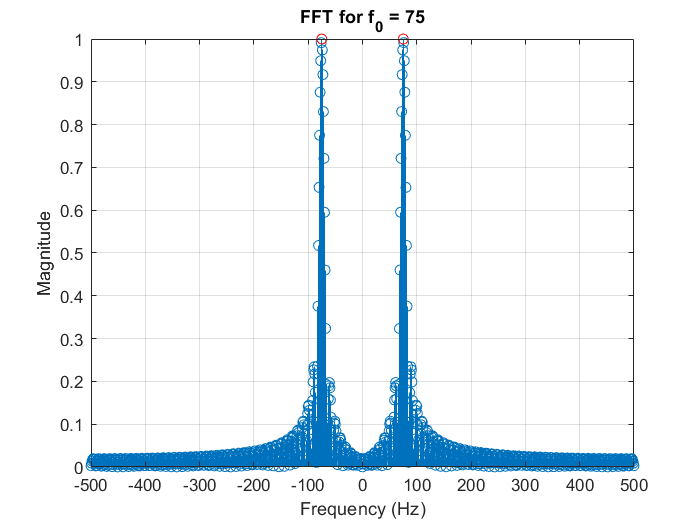

fs = 1000;T = 0.1; t = 0:1/fs:T; f0 = 75; N = fs+1;
x_a1 = cos(2*pi*f0*t);
y = fftshift(fft(x_a1,N));
f = -fs/2:fs/(N-1):fs/2;
X=abs(y)/max(abs(y));
ix = find(X==max(X));
stem(f,X);
xlabel('Frequency (Hz)')
ylabel('Magnitude')
title('FFT for f_0 = 75');
grid;
hold on
plot([f(ix(1)) f(ix(2))], [X(ix(1)) X(ix(2))], 'ro')
hold off

fprintf('Estimated frequency is equals to: %f\n',f(ix));

Estimated frequency is equals to: -75.000000
Estimated frequency is equals to: 75.000000



$$2\ldotp f_0 =75\ldotp 5\;\textrm{Hz}$$


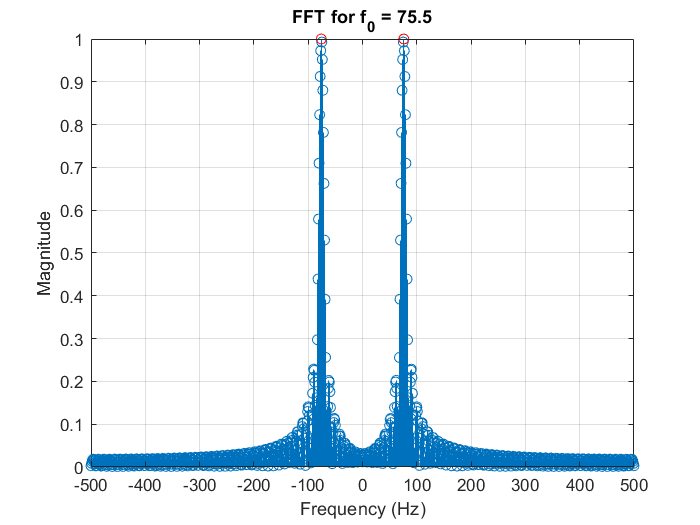

fs = 1000;T = 0.1; t = 0:1/fs:T; f0 = 75.5; N = fs+1;
x_a1 = cos(2*pi*f0*t);
y = fftshift(fft(x_a1,N));
f = -fs/2:fs/(N-1):fs/2;
X=abs(y)/max(abs(y));
ix = find(X==max(X));
stem(f,X);
xlabel('Frequency (Hz)')
ylabel('Magnitude')
title('FFT for f_0 = 75.5');
grid;
hold on
plot([f(ix(1)) f(ix(2))], [X(ix(1)) X(ix(2))], 'ro')
hold off

fprintf('Estimated frequency is equals to: %f\n',f(ix));

Estimated frequency is equals to: -76.000000
Estimated frequency is equals to: 76.000000


Estimation with Interpolation:

fest1 = sample_interpolator(X,ix(1),f(ix(1)))

fest1 = -75.6618

fprintf('Estimated frequency with interpolator is equals to: %f\n',fest1);

Estimated frequency with interpolator is equals to: -75.661761


fest2 = sample_interpolator(X,ix(2),f(ix(2)))

fest2 = 75.6618

fprintf('Estimated frequency with interpolator is equals to: %f\n',fest2);

Estimated frequency with interpolator is equals to: 75.661761


$N=2\times f_s$    , $f_0 =75\ldotp 5\;\textrm{Hz}$

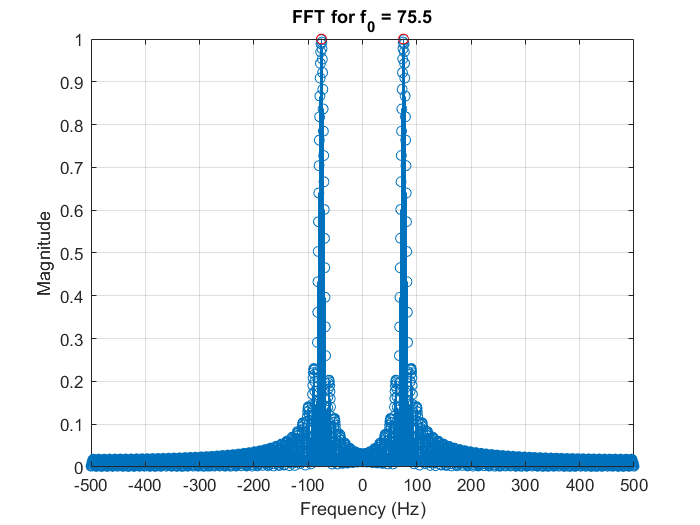

fs = 1000;T = 0.1; t = 0:1/fs:T; f0 = 75.5; N = 2*fs+1;
x_a1 = cos(2*pi*f0*t);
y = fftshift(fft(x_a1,N));
f = -fs/2:fs/(N-1):fs/2;
X=abs(y)/max(abs(y));
ix = find(X==max(X));
stem(f,X);
xlabel('Frequency (Hz)')
ylabel('Magnitude')
title('FFT for f_0 = 75.5');
grid;
hold on
plot([f(ix(1)) f(ix(2))], [X(ix(1)) X(ix(2))], 'ro')
hold off

fprintf('Estimated frequency is equals to: %f\n',f(ix));

Estimated frequency is equals to: -75.500000
Estimated frequency is equals to: 75.500000


### **Part 2**


$$x\left(t\right)=\left\lbrace \begin{array}{cc}
10 & ,0\le t\le 30\mu s\\
0 & ,30\mu s<t\le 3\mathrm{ms}
\end{array}\right.$$


1.$I=0$

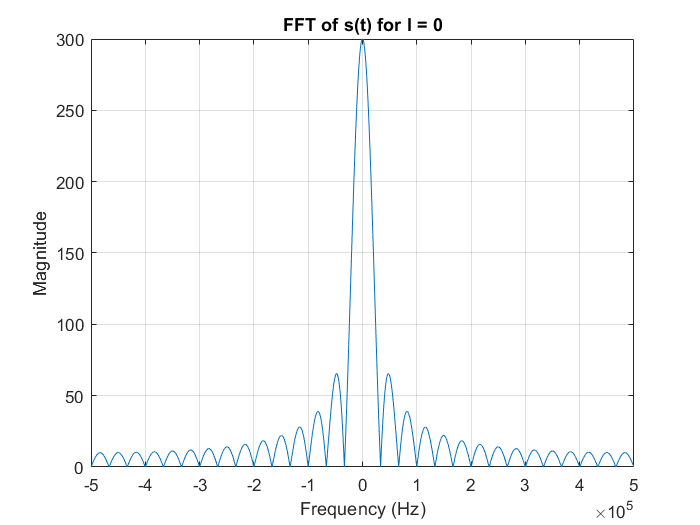

M = 3000; fs= 10^6;
x = zeros(1,M);
x(1:30) = 10;
I=0;
s = [];
for i = 0:I
    s = [s x];
end
N=M;
X = fftshift(fft(s));
f = -fs/2:fs/N:fs/2 - fs/N;
plot(f,abs(X));
xlabel('Frequency (Hz)')
ylabel('Magnitude')
title('FFT of s(t) for I = 0');
grid;

fprintf("3dB bandwidth for s0 is %f", BW3db(X))

3dB bandwidth for s0 is 0.186401

fprintf("first root is in %f Hz", find_first_root(X,f))

k = 100.000000
first root is in 33333.333333 Hz

2.$I=2$

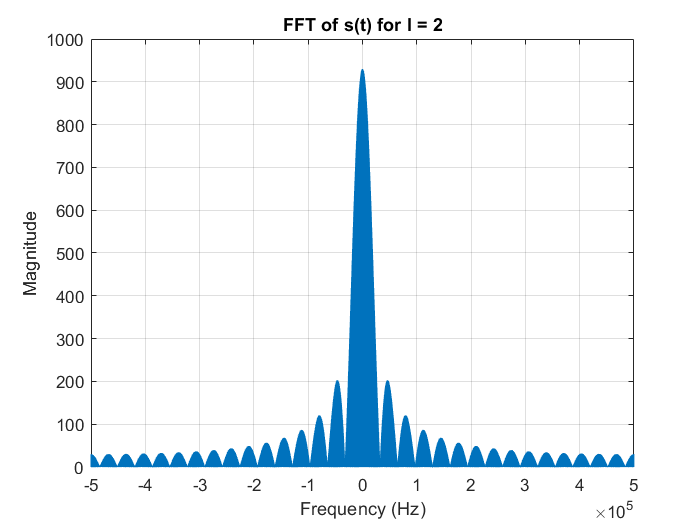

I=2;
M = 3000; fs= 10^6;
x = zeros(1,M);
x(1:31) = 10;
s = [];
for i = 0:I
    s = [s x];
end
N = (I+1)*3000;
X = fftshift(fft(s));
f = -fs/2:fs/N:fs/2- fs/N;
plot(f,abs(X));
xlabel('Frequency (Hz)')
ylabel('Magnitude')
title('FFT of s(t) for I = 2');
grid;

fprintf("3dB bandwidth for s2 is %f", BW3db(X))

3dB bandwidth for s2 is 0.059341

fprintf("first root is in %f Hz", find_first_root(X,f))

k = 1.000000
first root is in 111.111111 Hz

3.$I=10$

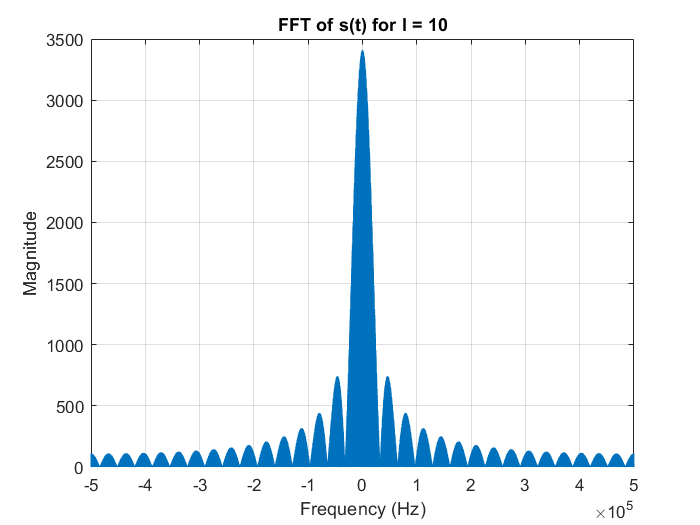

I=10;
M = 3000; fs= 10^6;
x = zeros(1,M);
x(1:31) = 10;
s = [];
for i = 0:I
    s = [s x];
end
N = (I+1)*3000;
X = fftshift(fft(s));
f = -fs/2:fs/N:fs/2- fs/N;
plot(f,abs(X));
xlabel('Frequency (Hz)')
ylabel('Magnitude')
title('FFT of s(t) for I = 10');
grid;

fprintf("3dB bandwidth for s10 is %f", BW3db(X))

3dB bandwidth for s10 is 0.016184

fprintf("first root is in %f Hz", find_first_root(X,f))

k = 1.000000
first root is in 30.303030 Hz

### **Part 3**

1. load data and time representation:

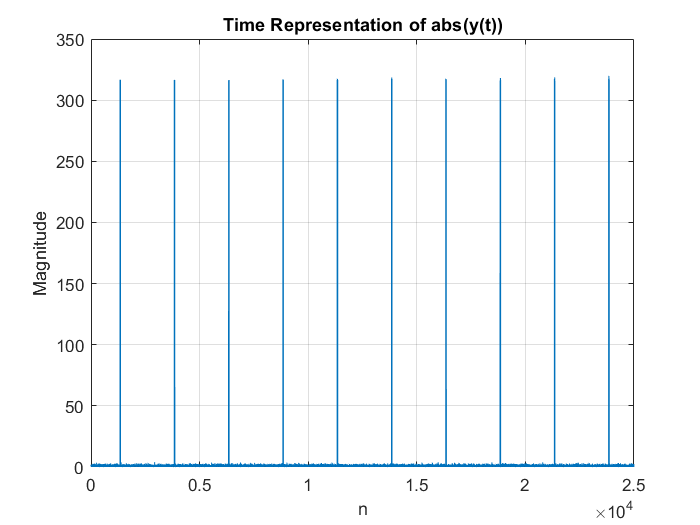

load('data.mat')
plot(abs(y))
title('Time Representation of abs(y(t))');
xlabel('n')
ylabel('Magnitude')
grid;

2. construct suitable $x\left(t\right)$

M = 2500; fs= 10^6;
x = zeros(1,M);
x(1:25) = 316;
I=9;
s = [];
for i = 0:I
    s = [s x];
end

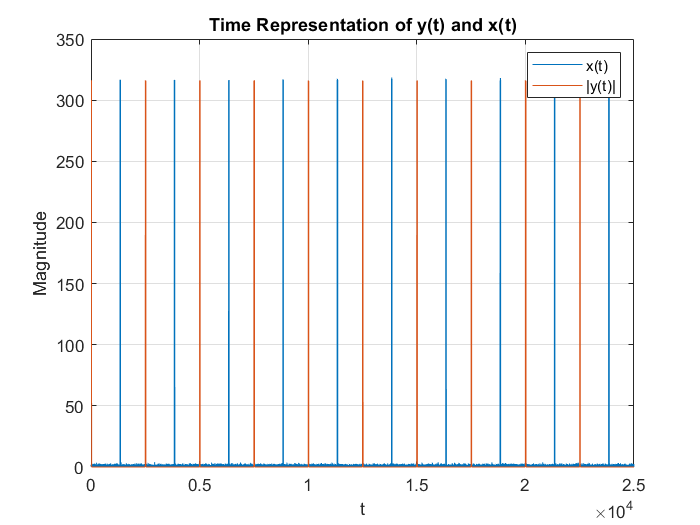

figure;
plot(abs(y))
hold on;
plot(s);
title('Time Representation of y(t) and x(t)');
xlabel('t')
ylabel('Magnitude')
grid;
hold off
legend('x(t)','|y(t)|')

3. find $R_0$ with Cross-correlation

ro = xcorr(s,y);
nx = mod(find(ro==max(ro)), 2500);
R0 = 0.5*3*10^8*nx*10^-6;

so we can easily find out that the time delay is 1334 $\times$ $10^{-6}$.

also:

we have 10 pulses (I = 10).

period is 2500 points. each point is $10^{-6}$ s. $\Longrightarrow$ T = 2.5 ms

pulse length is 24 points. $\Longrightarrow$ pulse length = 24 $\mu$s.

Now we analyse signals at frequency domain in order to compute the frequency delay by $|X(f)|$ and $|Y(f)|$:

4. find Doppler frequency with fourier transform

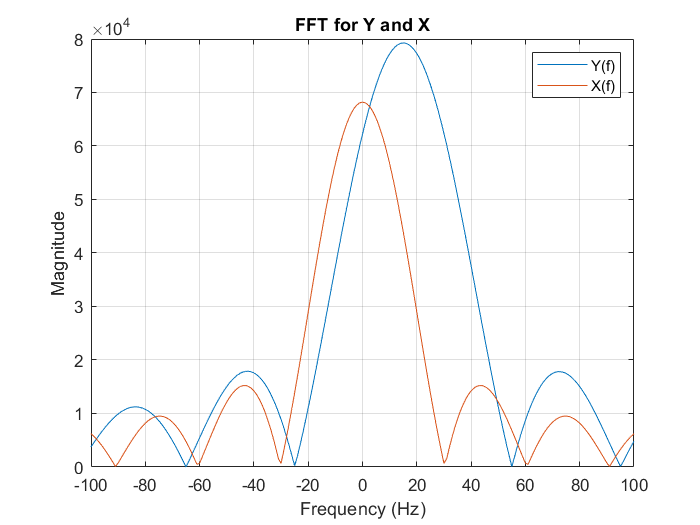

Y = fftshift(fft(y,fs));
I = 9;
Y = abs(Y);
S = fftshift(fft(s,fs));
S = abs(S);
N = length(Y);
f = (-N/2:N/2-1)/N*fs;
figure
plot(f,Y);
hold on;
plot(f,20*S);
xlabel('Frequency (Hz)')
ylabel('Magnitude')
title('FFT for Y and X');
legend('Y(f)','X(f)')
grid;
xlim([-100 100])
hold off;


$$\Longrightarrow$$
 
$$f_d = 15 (frequency \ delay \ of \ Y(f))$$



$$\lambda = 3$$



$$15 = \frac{2v}{\lambda} \Longrightarrow v = 22.5\frac{m}{s} = 81\frac{Km}{h}$$



$$\frac{2R_0}{c} = 1333 \times 10^{-6} \Longrightarrow R_0 = 199950m\ \  (time \  delay \ of \ y(t))$$
 

### Part 3-5

we are sampling with frequency of $10^6$ . so the minimum delay that can be calculated is $10^{-6}$ that makes the distance of 150m. so we have error of $\pm 75 m$.

we have $10^6$ samples over the sampling frequency(fft with N= $f_s$) . so the minimum $f_d$ that can be calculated is 1. so we have the error of $\pm 0.5$.


$$\hat{f_d} = f_d \pm 0.5 \Longrightarrow \hat{v} = v \pm 2.7(\frac{Km}{h})$$
 


$$\hat{R_0} = R_0 \pm 75 m$$


function y = sample_interpolator(X, f_I, f_hat)
    y = f_hat + 1.25*(3*X(f_I+3)+2*X(f_I+2)+ ...
    X(f_I+1)-X(f_I-1)-2*X(f_I-2)-3*X(f_I-3));
end
function y = BW3db(x)
    N = length(x);
    M = max(abs(x));
    counter = 0;
    for n = 1:N
        if abs(x(n)) > sqrt(2)/2*M
            counter = counter +1;
        end
    end
    y = counter/n *2*pi;
end
function y = find_first_root(X, f)
    epsilon = 10^-13;
    ix = find(abs(X) < epsilon);
    [~,c] = find(f(ix) > 0,1);
    y = f(ix(c));
    fprintf("k = %f\n",ix(c) - length(X) / 2 - 1)
end